**Querying the Gene Ontology Database**

In this tutorial, I am looking at several questions that make use of the Gene Ontology (GO) database and build SQL queries to answer these questions. In each case, I work step-by-step to build the final query. When you are designing your own queries, I recommend that you also work step-by-step; but your final work should only contain the final query that you come up with.

Gene Ontology Database contains information about biological terms (GO  terms). GO terms include biological processes, molecular functions, and  cellular localization; such as "nucleus", "apoptosis", "positive  regulation of inflammatory response". GO database also provides  associations between genes to GO terms. GO database is one of the  primary resources that researchers use to look up the functionality of  genes, as described by GO terms.

The tables used in this tutorial include: species, gene_product (information about genes), term (where GO terms are listed), graph_path (where relationships between terms are listed), association (which acts as a join table between terms and gene_products).

GO terms are organized in a hierarchical structure, e.g., the term "nucleus" would encompass other terms like "nuclear chromosome", "nuclear membrane", etc. The relationship between terms is represented in the graph_path table that joins different terms. In order to find all genes associated with the term "nucleus", you need to first collect all the other terms encompassed under "nucleus" by collecting them from the graph_path table, and then using the association table to join all these terms with the genes that are associated with.

The database schema can also be found at: http://www-legacy.geneontology.org/images/diag-godb-er.jpg

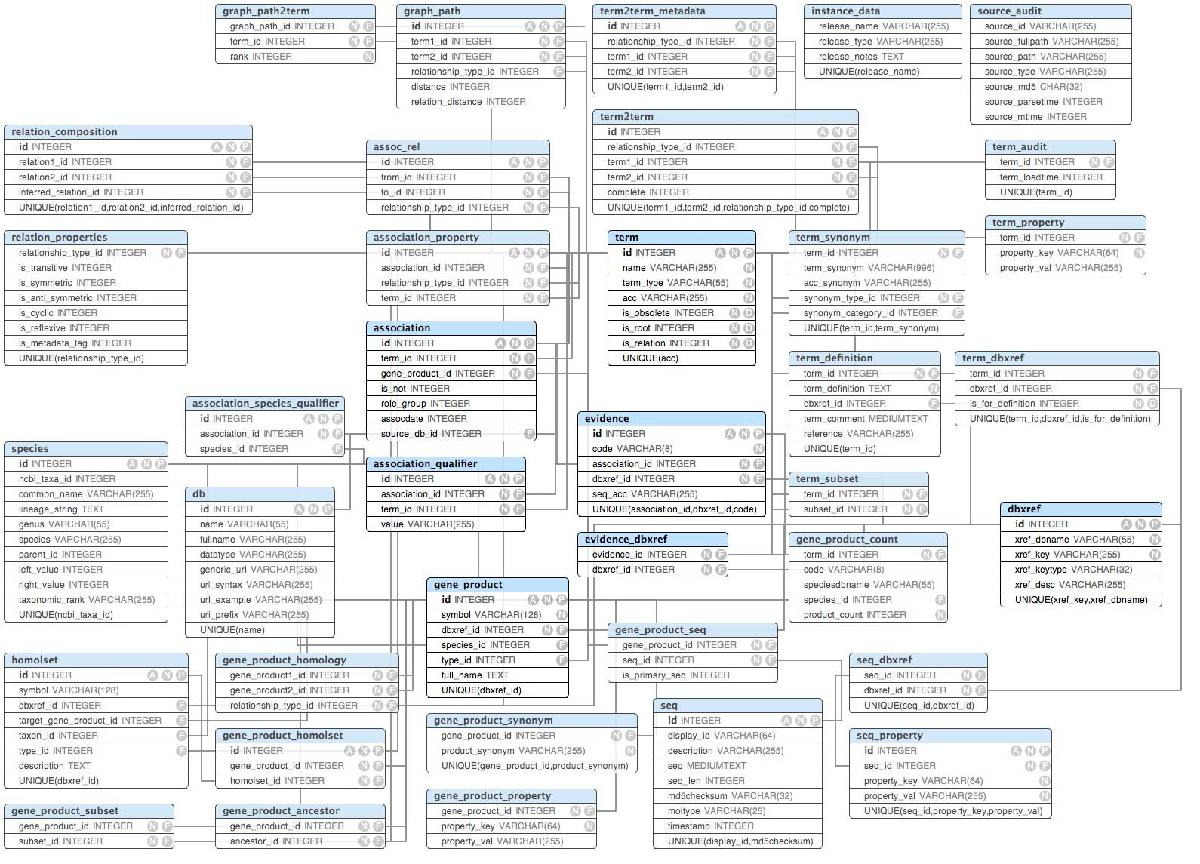

%this is a large file and the download may take some time...
godbfile = bmes.downloadurl('http://sacan.biomed.drexel.edu/ftp/binf/godb.sqlite')

godbfile = 'C:\Users\ahmet/Downloads/godbbinfftpsacan.biomed.drexel.edu.sqlite'

db = bmes_db(godbfile,'database');

**•Retrieve the names of the species that are under the genus ‘Drosophila’**

db.query(['SELECT genus,species ' ...
	' FROM species ' ...
	' WHERE genus="Drosophila" ' ...
  ' LIMIT 0,10'])

ans = 10×1 struct array with fields:
    genus
    species


**•Retrieve the genus and species name of the organisms  whose species name has a prefix ‘mel’ (use LIKE function).	**

db.query(['SELECT genus,species ' ...
	' FROM species ' ...
	' WHERE species LIKE "mel%" ' ...
	' LIMIT 0,10'])

ans = 10×1 struct array with fields:
    genus
    species


**•Retrieve the gene symbols (gene_product.symbol) of all Drosophila melanogaster (species.genus, species.species) genes that are annotated to the ‘nucleus’.**

Below, I progressively build the query, joining with more and more related tables until all the required tables are referenced. The last query below shows the final query and its result.

–Join path: term.id -> graph_path.term1_id /term2_id -> association.term_id /gene_product_id -> gene_product.id

Join path: gene_product.species_id -> species.id

db.query(['SELECT * ' ...
	' FROM gene_product ' ...
	' LIMIT 0,5'])

ans = 5×1 struct array with fields:
    id
    symbol
    dbxref_id
    species_id
    type_id
    full_name


db.query(['SELECT gene_product.* ' ...
	' FROM gene_product, species ' ...
	' WHERE species.genus="Drosophila" AND species="melanogaster" ' ...
	' AND  species.id = gene_product.species_id' ...
	' LIMIT 0,5'])

ans = 5×1 struct array with fields:
    id
    symbol
    dbxref_id
    species_id
    type_id
    full_name


db.query(['SELECT * ' ...
	' FROM term' ...
	' LIMIT 1000,5'])

ans = 5×1 struct array with fields:
    id
    name
    term_type
    acc
    is_obsolete
    is_root
    is_relation


db.query(['SELECT * ' ...
	' FROM term' ...
	' WHERE name LIKE "nucleus" ' ...
	' LIMIT 0,5'])

ans = struct with fields:
             id: 4673
           name: 'nucleus'
      term_type: 'cellular_component'
            acc: 'GO:0005634'
    is_obsolete: 0
        is_root: 0
    is_relation: 0


db.query(['SELECT t2.* ' ...
	' FROM term AS t1, graph_path, term AS t2' ...
	' WHERE t1.name="nucleus" ' ...
	' AND t1.id = graph_path.term1_id ' ...
	' AND graph_path.term2_id = t2.id' ...
	' LIMIT 0,5'])

ans = 5×1 struct array with fields:
    id
    name
    term_type
    acc
    is_obsolete
    is_root
    is_relation


db.query(['SELECT association.id, association.term_id, association.gene_product_id' ...
	' FROM term AS t1, graph_path, term AS t2, association' ...
	' WHERE t1.name="nucleus" ' ...
	' AND t1.id = graph_path.term1_id ' ...
	' AND graph_path.term2_id = t2.id' ...
	' AND t2.id = association.term_id ' ...
	' LIMIT 0,5'])

ans = 5×1 struct array with fields:
    id
    term_id
    gene_product_id


db.query(['SELECT t2.name as termname, gene_product.* ' ...
	' FROM term AS t1, graph_path, term AS t2, association, gene_product' ...
	' WHERE t1.name="nucleus" ' ...
	' AND t1.id = graph_path.term1_id ' ...
	' AND graph_path.term2_id = t2.id' ...
	' AND t2.id = association.term_id ' ...
	' AND association.gene_product_id = gene_product.id ' ...
	' LIMIT 0,5'])

ans = 5×1 struct array with fields:
    termname
    id
    symbol
    dbxref_id
    species_id
    type_id
    full_name


db.query(['SELECT gene_product.* ' ...
	' FROM term AS t1, graph_path, term AS t2, association, gene_product, species' ...
	' WHERE t1.name="nucleus" ' ...
	' AND t1.id = graph_path.term1_id ' ...
	' AND graph_path.term2_id = t2.id' ...
	' AND t2.id = association.term_id ' ...
	' AND association.gene_product_id = gene_product.id ' ...
	' AND species.genus="Drosophila" AND species="melanogaster" ' ...
	' AND  species.id = gene_product.species_id' ...
	' LIMIT 0,5'])

ans = 5×1 struct array with fields:
    id
    symbol
    dbxref_id
    species_id
    type_id
    full_name


%This is the final form of the query to answer the question above:
rs=db.query(['SELECT DISTINCT(gene_product.symbol) ' ...
	' FROM term AS t1, graph_path, term AS t2, association, gene_product, species' ...
	' WHERE t1.name="nucleus" ' ...
	' AND t1.id = graph_path.term1_id ' ...
	' AND graph_path.term2_id = t2.id' ...
	' AND t2.id = association.term_id ' ...
	' AND association.gene_product_id = gene_product.id ' ...
	' AND species.genus="Drosophila" AND species="melanogaster" ' ...
	' AND  species.id = gene_product.species_id']);

rs = 2377×1 struct array with fields:
    symbol



fprintf('Number of genes found: [%d]. The first 10 of these genes are listed below:\n',numel(rs));

Number of genes found: [2377]. The first 10 of these genes are listed below:


rs=struct2cell(rs);
disp(strjoin(rs(1:10),', '))

14-3-3epsilon, 14-3-3zeta, 2.1, 33-13, 4E-T, ADD1, AGO1, AGO2, AMPKalpha, AP-1mu
